ans = "Signal 12: 21:36 Actual force [kN]"

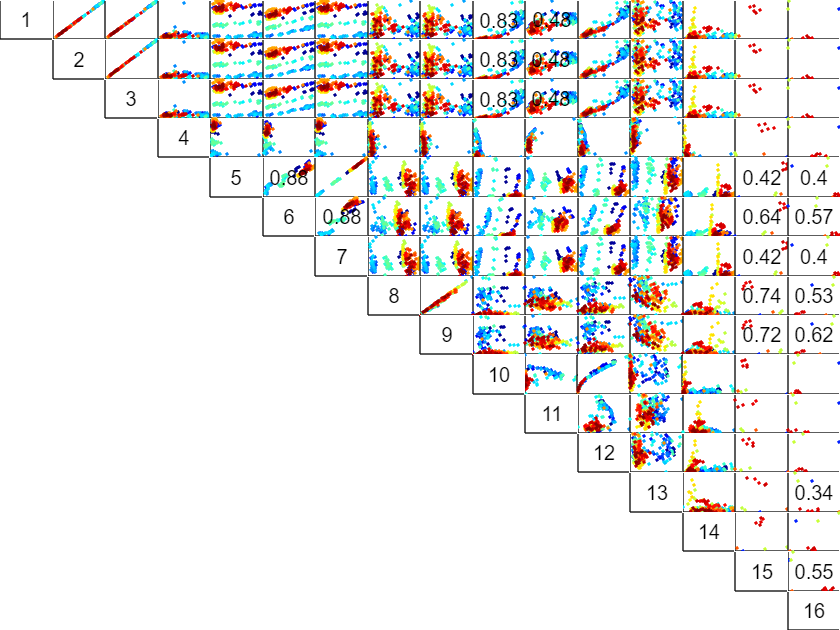

Features = DFD_FeatureTable_TimeDomain;
FeatureNames = FeatureNames_Combined;
lowerR2 = 0.3;
upperR2 = 0.9;
r2ReducedThreshold = 0.9;
selectedSignal = 12; % 21:34 & Error position for the width
saveFigures = true;
R2 = fnPlotFeatureVsFeature_Array(featureArray, lowerR2, upperR2, selectedSignal, FeatureNames, sensorNames);

disp(num2str(R2, '%.2f  '));

1.00  1.00  1.00  0.02  0.24  0.02  0.24  0.03  0.03  0.83  0.48  0.91  0.02  0.00  0.01  0.00
0.00  1.00  1.00  0.02  0.24  0.02  0.24  0.03  0.03  0.83  0.48  0.91  0.02  0.00  0.01  0.00
0.00  0.00  1.00  0.02  0.24  0.02  0.24  0.03  0.03  0.83  0.48  0.91  0.02  0.00  0.01  0.00
0.00  0.00  0.00  1.00  0.03  0.02  0.03  0.05  0.05  0.00  0.28  0.00  0.03  0.02  0.07  0.19
0.00  0.00  0.00  0.00  1.00  0.88  1.00  0.00  0.00  0.23  0.20  0.20  0.03  0.01  0.42  0.40
0.00  0.00  0.00  0.00  0.00  1.00  0.88  0.00  0.00  0.03  0.05  0.01  0.02  0.02  0.64  0.57
0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.00  0.00  0.23  0.19  0.20  0.03  0.01  0.42  0.40
0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.99  0.01  0.08  0.01  0.06  0.12  0.74  0.53
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.01  0.08  0.01  0.11  0.13  0.72  0.62
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.24  0.96  0.02  0.00  0.12  0.18
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.

## Combination 1

selectedFeature = 1;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

     1    10    11

     1    10    11



figure(); hold on;
sensorNames(selectedSignal)%title(sensorNames(selectedSignal));

ans = "21:36 Actual force [kN]"

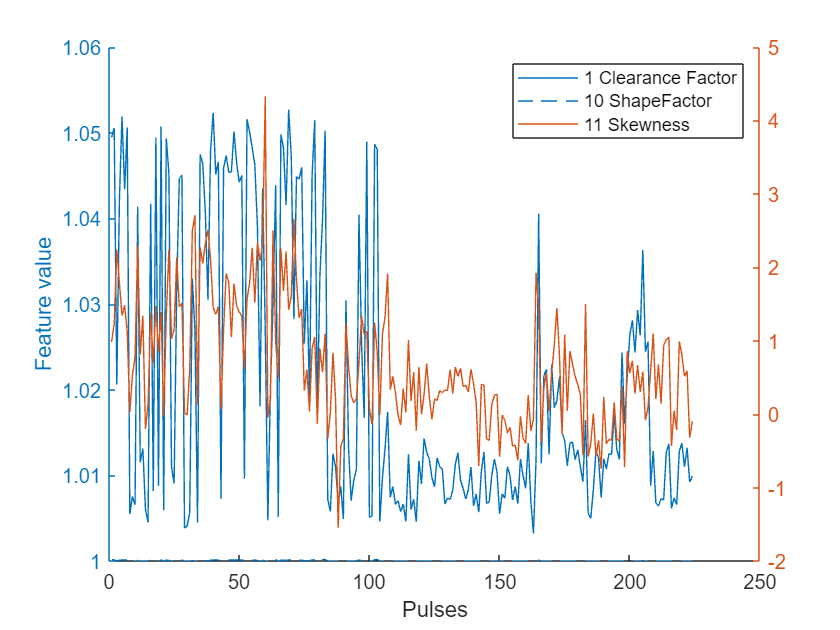

xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [3];
legendAxis = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
        ha = plot(selectedFeatureData{i});
        legendAxis = [legendAxis ha];
    else
        yyaxis left;
        hb = plot(selectedFeatureData{i});
        legendAxis = [legendAxis hb];
    end
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
hold off;
legend(legendAxis, leg)


% if (saveFigures == true)
%     filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
%     print(filename,'-depsc','-tiff')
% end

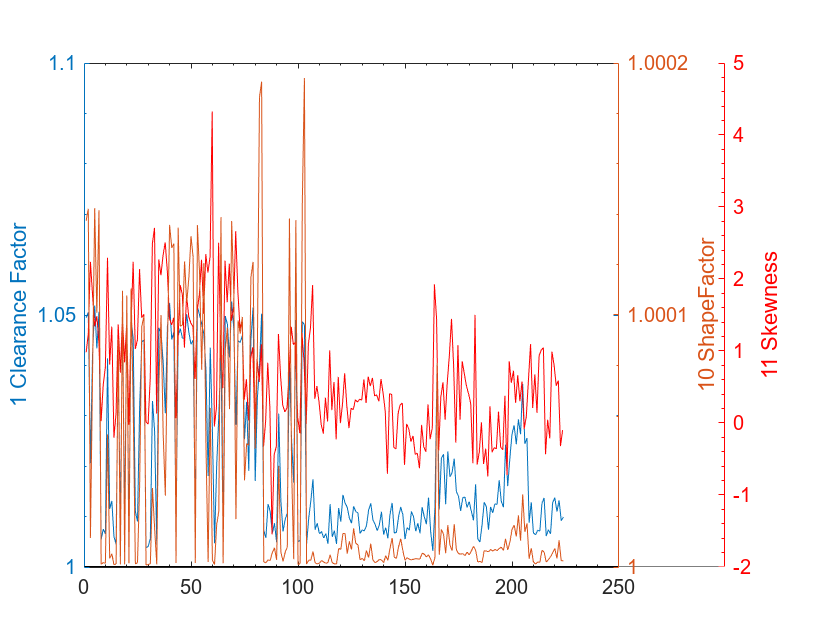

Error using print
Cannot read from source: C:\Users\PaulBarron\Dropbox\Thesis\Latex Document\figures\Models_Signal12Feature1.eps.

xx = 1:numOfPulses;
plotyyy(xx', selectedFeatureData{1}, xx', selectedFeatureData{2}, xx', selectedFeatureData{3}, leg);
if (saveFigures == true)
     filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
     print(filename,'-depsc','-tiff')
end

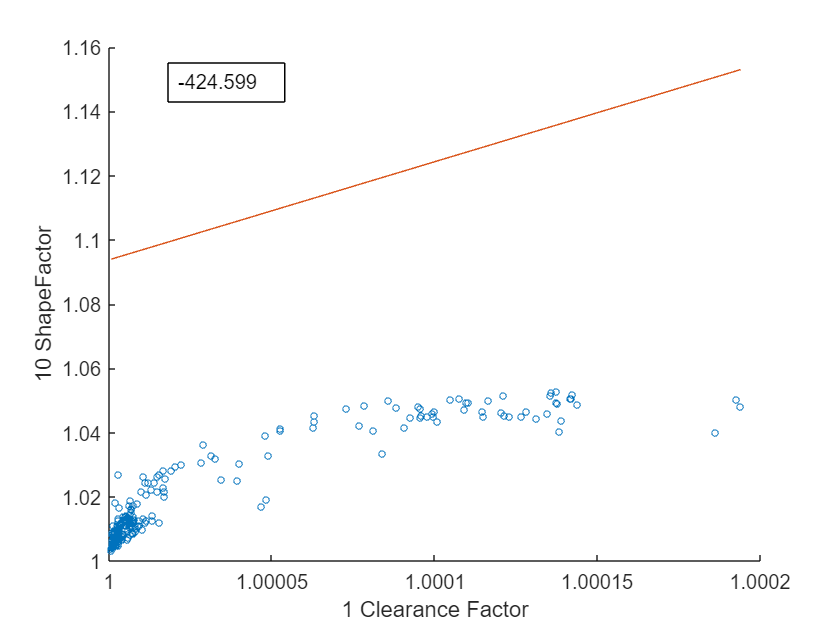

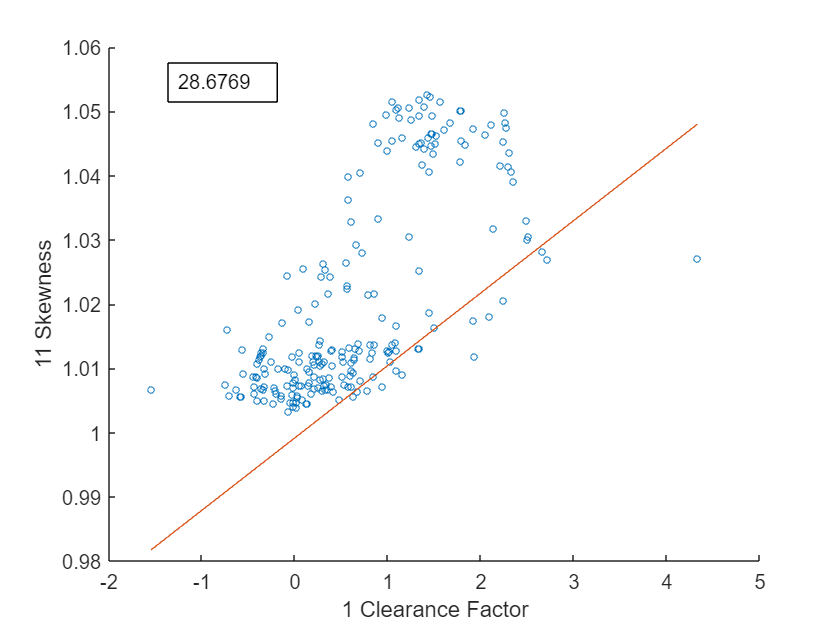

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
linearModelNum = 1;
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end

multivariateModelNum = 1;
if numOfSelectedFeatures > 2
    for index1 = 2 : numOfSelectedFeatures
        for index2 = index1+1 : numOfSelectedFeatures
            if selectedFeatureArray(index1) ~= selectedFeature && selectedFeatureArray(index2) ~= selectedFeature            
                Y_est = fnPlotModel3D( ...
                    selectedFeatureData{selectedFeatureIdx}, ...
                    selectedFeatureData{index1}, ...
                    selectedFeatureData{index2}, ...
                    sensorNames(selectedSignal), ...
                    FeatureNames(selectedFeatureArray(selectedFeatureIdx)), ...
                    FeatureNames(selectedFeatureArray(index1)), ...
                    FeatureNames(selectedFeatureArray(index2)));
                if (saveFigures == true)
                    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                        + "Feature" + selectedFeature ...
                        + "_Multivariate" + multivariateModelNum;
                    export_fig(filename, '-eps', '-depsc');
                    multivariateModelNum = multivariateModelNum + 1;
                end
            end
        end
    end
end

## Combination 2

selectedFeature = 5;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

figure(); hold on;
sensorNames(selectedSignal)%title(sensorNames(selectedSignal));
xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [];
legendAxis = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
        ha = plot(selectedFeatureData{i});
        legendAxis = [legendAxis ha];
    else
        yyaxis left;
        hb = plot(selectedFeatureData{i});
        legendAxis = [legendAxis hb];
    end
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
hold off;
legend(legendAxis, leg)

if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
    print(filename,'-depsc','-tiff')
end

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
linearModelNum = 1;
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end